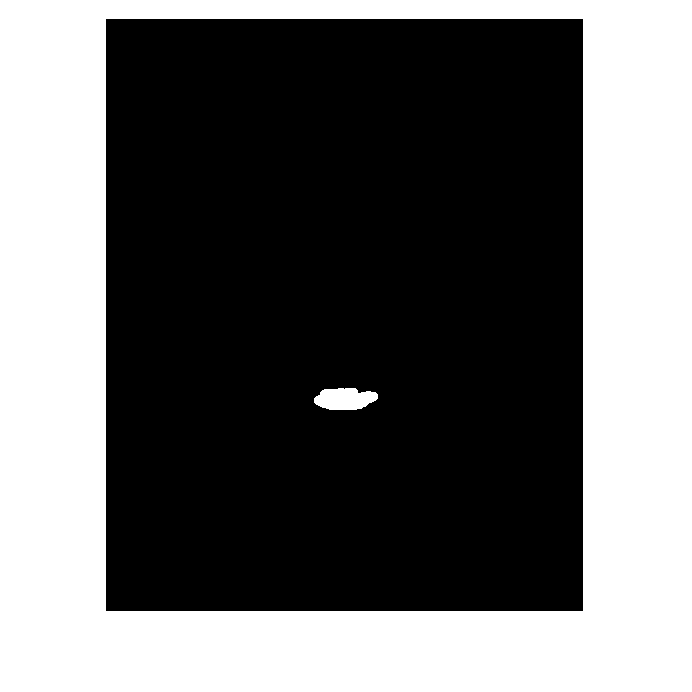

clear
% Read img file
img = imread("../db/DB0/db0_3.jpg");

% Normalize colors
img_gw = gray_world(img);

% Create facemask 
face_mask = facemask(img_gw);
imshow(face_mask)

%Find eyes and a mouth
eyes = eyemap(img_gw);
eye_mask = eyemask(eyes) & face_mask;

mouth = mouth_map(img_gw);
mouth_mask = mouthmask(mouth) & face_mask;
imshow(mouth_mask)


[x,y] = mouth_index(mouth_mask)

x = 380

y = 240


[indexX,indexY] = eye_index(eye_mask)

indexX = -1

indexY = -1

mouth_center = [x, y]; % replace with actual coordinates
[eye1 , eye2, angle] = findEyePair(indexX,indexY,mouth_center);

Index exceeds the number of array elements. Index must not exceed 1.

Error in findEyePair (line 17)
selected_eye_indices = sorted_indices(1:2);


% Visualize the original image with detected eyes and mouth
figure;
imshow(img);
hold on;
viscircles([eye1; eye2], 10, 'EdgeColor', 'r');
plot([eye1(1), eye2(1)], [eye1(2), eye2(2)], 'LineWidth', 2, 'Color', 'r')